Defining the paths to data

path_to_seg_results = '/Users/ali/Desktop/exp1_seg_gif_with_roi/';
min_cell_log_area = 5;
n_trenches = 8*ones(1,20);
n_trenches(1,3) = 7;
n_trenches(1,17) = 7;


for f=0:0 %iterating over FOVs
    fov = "xy"+num2str(f,'%03d'); %fov name
    for tr=0:0   %n_trenches(1,f+1)
        fov + " tr"+tr
        
        %paths to segmentation "mCherry" csv and info "YFP" csv
        path_to_data_seg = path_to_seg_results+fov+'/Data/data_'+fov+'_tr_'+tr+'_mCherry.csv'; 
        path_to_data_info = path_to_seg_results+fov+'/Data/data_'+fov+'_tr_'+tr+'_YFP.csv';  
        %converting csvs to matrices
        seg = table2array(readtable(path_to_data_seg,'VariableNamingRule','preserve')); % convert table to an array
        info = table2array(readtable(path_to_data_info,'VariableNamingRule','preserve'));
        %taking intensity information from info matrix and adding to end of seg
        %matrix
        A = [seg,info(:,[23,27])];
        clear seg info
        
        A=sortrows(A,28);% sort the data in time
        A=A((log(A(:,2))>min_cell_log_area),:); %remove anythingto small

        data = nan(721,37);
        for t=1:721
            cur = A((A(:,28)==t),:);
            cur = sortrows(cur,11,"ascend");
            if(size(cur,1)>0)
                data(t,:) = cur(1,:);
            end
        end
    end
end

ans = "xy000 tr0"


clearvars -except data

# Compare Prediction Intervals of GPR Models

This example fits GPR models to a noise-free data set and a noisy data set. The example compares the predicted responses and prediction intervals of the two fitted GPR models. 

Generate two observation data sets from the function $g\left(x\right)=x\cdot \sin \left(x\right)$. 

rng('default') % For reproducibility
x_observed1 = linspace(1,721,721)';
y_observed1 = log(data(:,2));

The values in `y_observed1` are noise free, and the values in `y_observed2` include some random noise. 

Fit GPR models to the observed data sets.

sigma0 = std(y_observed1);
sigmaF0 = sigma0;
d = size(x_observed1,2);
sigmaM0 = 10*ones(d,1);

gprMdl1 = fitrgp(x_observed1,y_observed1);

Compute the predicted responses and 95% prediction intervals using the fitted models. 

x = linspace(1,721)';
[ypred1,~,yint1] = predict(gprMdl1,x);

For each tile, draw a scatter plot of observed data points and a function plot of $x\cdot \sin \left(x\right)$. Then add a plot of GP predicted responses and a patch of prediction intervals. 

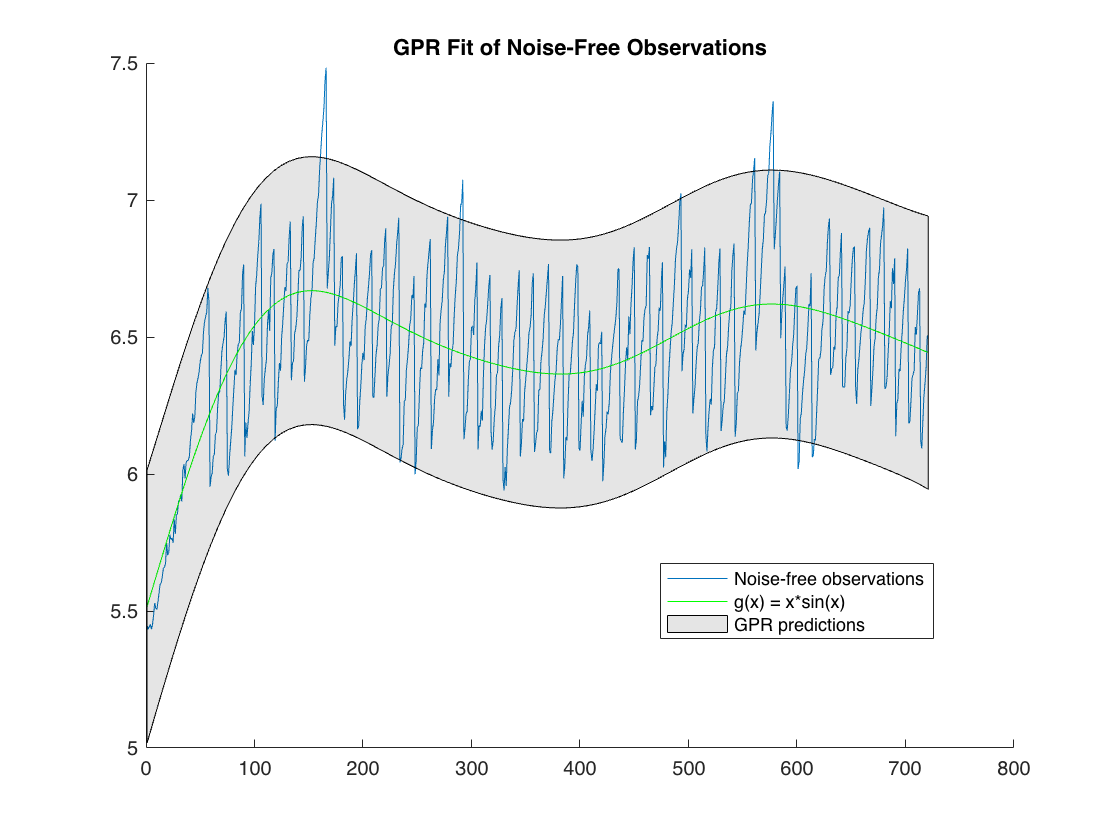

hold on
plot(log(data(:,2)))
plot(x,ypred1,'g')                  % GPR predictions
patch([x;flipud(x)],[yint1(:,1);flipud(yint1(:,2))],'k','FaceAlpha',0.1); % Prediction intervals
hold off
title('GPR Fit of Noise-Free Observations')
legend({'Noise-free observations','g(x) = x*sin(x)','GPR predictions','95% prediction intervals'},'Location','best')

When the observations are noise free, the predicted responses of the GPR fit cross the observations. The standard deviation of the predicted response is almost zero. Therefore, the prediction intervals are very narrow. When observations include noise, the predicted responses do not cross the observations, and the prediction intervals become wide. 

*Copyright 2020 The MathWorks, Inc.*